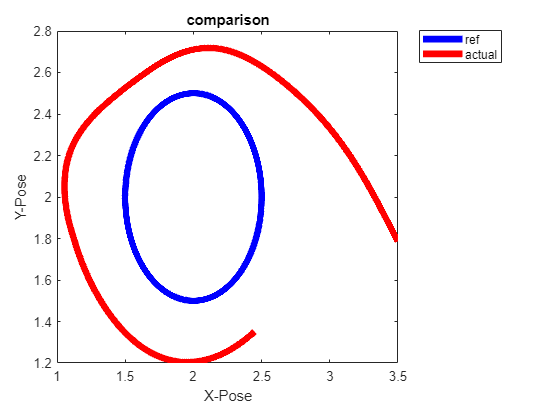

clear; % clears all var
clc; % clears command window
%data = load("third_successful.mat");
data = load("fifth_successful.mat");
ref = load("reference.mat");
ref_x = ref.C2(11,1:3772);
ref_y = ref.C2(12,1:3772);
ref_z = ref.C2(13,1:3772);

%data = load("second_successful.mat");
limit = 2000;
x = transpose(data.test(1:limit,1))+0.5;
y = transpose(data.test(1:limit,2))-1.3;
x_g = smoothdata(x,'gaussian',1000);
y_g = smoothdata(y,'gaussian',1000);
% bod_rates = transpose(data.test(1:limit,3)); 
% motor = transpose(data.test(1:limit,4));
% motor = smoothdata(motor,'gaussian',1000);
% bod_rates_g = smoothdata(bod_rates,'gaussian',1000);
% heading = rad2deg(transpose(data.test(1:limit,5)));
% pitch = rad2deg(transpose(data.test(1:limit,6)));
% pitch = smoothdata(pitch,'gaussian',1000);
% 
% 
% 
% 
% 
% 
% plot(time,smoothedbod_roll,'Color','b','linewidth',5)
figure(1)
plot(ref_x,ref_y,'Color','b','linewidth',5)
xlabel('X-Pose Ref')
ylabel('Y-Pose Ref')
title('Ref Pose')


% plot(x,y,'Color','b','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% title('Pose ')

hold on

plot(x_g,y_g,'Color','r','linewidth',5)
xlabel('X-Pose')
ylabel('Y-Pose')
%title('Pose w gaussian')
title('comparison')
legend('ref','actual');

hold off 

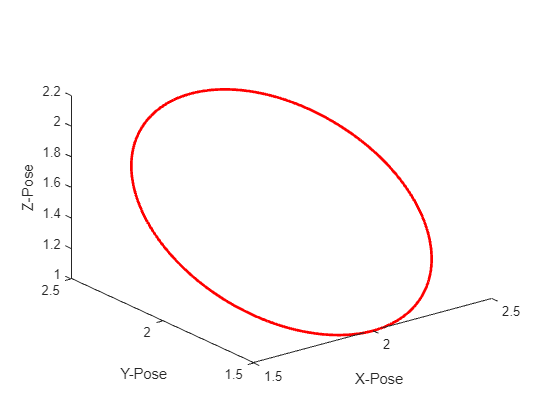


plot3(ref_x, ref_y, ref_z, 'Color','r','LineWidth',2);
xlabel('X-Pose')
ylabel('Y-Pose')
zlabel('Z-Pose')


% plot(1:limit,bod_rates_g,'Color','b','linewidth',5)
% xlabel('Time')
% ylabel('Bod Rates')
% title('Rates vs index')
% plot(1:limit,motor,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('Motor')
% title('Motor vs index')
% plot(1:limit,heading,'Color','b','linewidth',5)
% xlabel('Time')
% ylabel('heading')
% title('Heading vs index')
% plot(1:limit,pitch,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('pitch')
% title('Pitch vs index')